# Getting Characteristic Frequencies of Complex Transfer Functions

## High-Pass Filter with Low-Pass Stage - Numeric

syms R R_2 C C_2 omega f
% dont confuse matlab,
assume(omega>0)
assume(f>0)

% Define numerator ;and denominator of (complex) transfer function
% Also define their complex conjugates
num = R*(-1i/(C_2*omega));
num_conj = R*(1i/(C_2*omega));
denom = R*R_2 - 1/(C*C_2*omega^2) - (1i/omega)*(R_2/C + R/C_2);
denom_conj = R*R_2 - 1/(C*C_2*omega^2) + (1i/omega)*(R_2/C + R/C_2);
num_squared = simplify(num*num_conj);
denom_squared = simplify(denom*denom_conj);

T_squared = simplify(num_squared/denom_squared);
T = sqrt(T_squared)

$$T = \omega \,\sqrt{\frac{C^{2}\,R^{2}}{\left(C^{2}\,R^{2}\,\omega^{2}+1\right)\,\left({C_{2}}^{2}\,{R_{2}}^{2}\,\omega^{2}+1\right)}}$$


r = 100; % Ohms
r_2 = 150; % Ohms
c = 0.1 * 10^-6; % Farads
c_2 = 0.01*10^-6; % Farads

old = [R, R_2, C, C_2];
new = [r, r_2, c, c_2];
T = subs(T, old, new);
T = simplify(T);

% T = subs(T, omega, 2*pi*f)
equ = (1/sqrt(2)) == T;
omega_0 = solve(equ, omega);
digits(5);
omega_0 = vpa(omega_0);
omega_0 = omega_0(1)

$$omega\_0 = 102400.0$$

## High-Pass Filter with Low-Pass Stage - Symbolic

syms R_1 R_2 C_1 C_2 
% dont confuse matlab,

assume(R_1>0)
assume(R_2>0)
assume(C_1>0)
assume(C_2>0)

syms Z_C_1 Z_C_2 Z_R_1 Z_R_2 omega omega_0 V_1 V_in V_out x
assume(omega>0)

Z_R_1 = R_1;
Z_R_2 = R_2;
Z_C_1 = -1i/(C_1*omega);
Z_C_2 = -1i/(C_2*omega);

V_1 = V_in*(Z_R_1/(Z_R_1 + Z_C_1));
V_out = V_1*(Z_C_2/(Z_C_2+Z_R_2));
V_out = expand(V_out);
V_out = simplify(V_out);

z = V_out/V_in;
z = expand(z);
z_conj = conj(z);

T = sqrt(simplify(z*z_conj));
T = subs(T, [1/(R_1*C_1), 1/(R_2*C_2)], [omega_0, omega_0]);

syms x
T = subs(T, omega/omega_0, x)

$$T = \frac{x}{x^{2}+1}$$

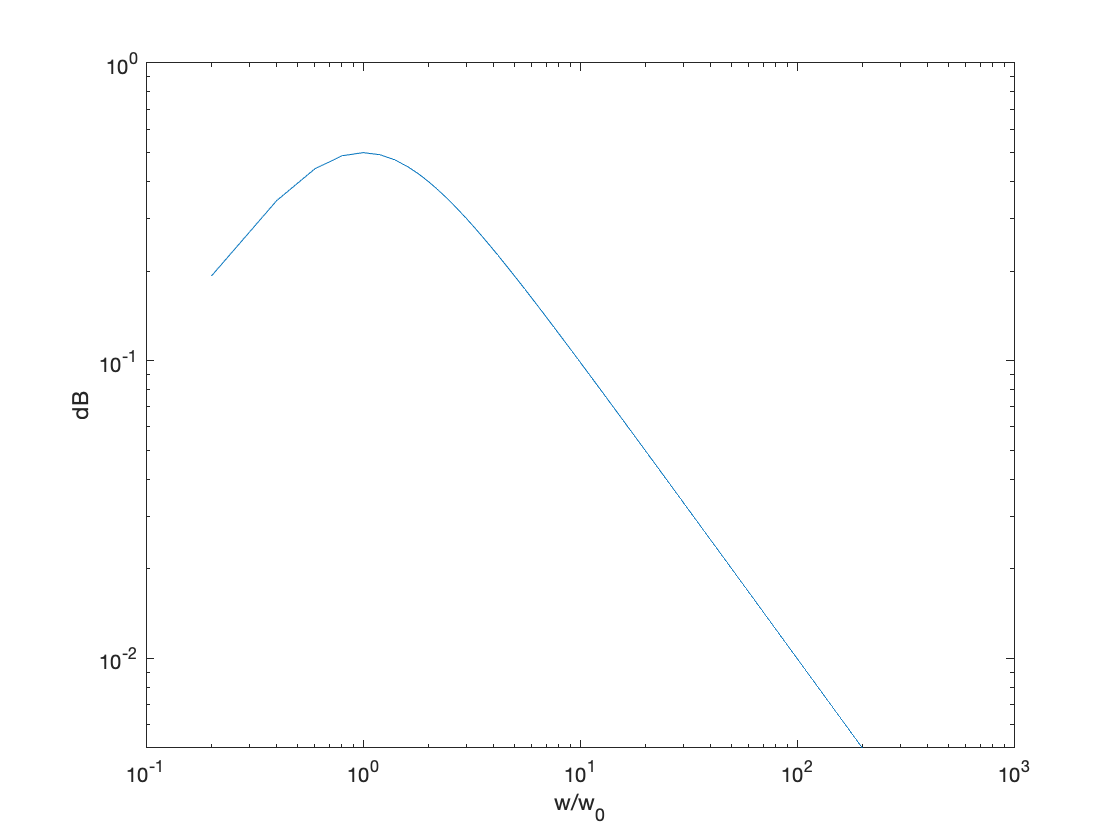

f(x) = @(x) T;
x = linspace(0, 200, 1000);
loglog(x, f(x))
xlabel("w/w_0")
ylabel("dB")

## Low-Pass Filter - Symbolic

syms R C omega omega_0 Z_R Z_C V_out V_in T x
% dont confuse matlab,
assume(omega>0)
assume(R>0)
assume(C>0)
assume(T>0)

Z_R = R;
Z_C = -1i/(omega*C);

V_out = (Z_C/(Z_R + Z_C))*V_in;
V_out = expand(V_out);
V_out = simplify(V_out);

z = V_out/V_in;
z_conj = conj(z);

T = sqrt(simplify(z*z_conj));
T = subs(T, 1/(R*C), omega_0);
T = subs(T, omega/omega_0, x)

$$T = \sqrt{\frac{1}{x^{2}+1}}$$

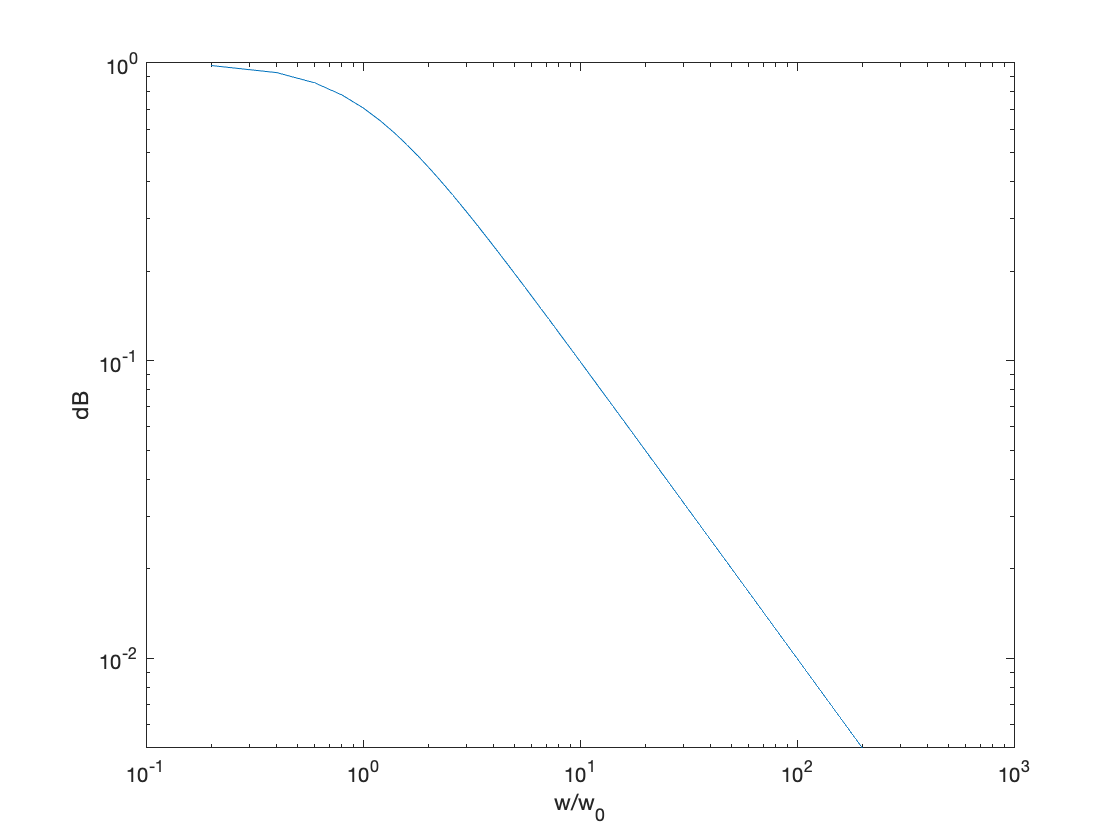


f(x) = @(x) T;
x = linspace(0, 200, 1000);
loglog(x, f(x))
xlabel("w/w_0")
ylabel("dB")

## High-Pass Filter - Symbolic

syms R C omega omega_0 Z_R Z_C V_out V_in T x
% dont confuse matlab,
assume(omega>0)
assume(R>0)
assume(C>0)
assume(T>0)

Z_R = R;
Z_C = -1i/(omega*C);

V_out = (Z_R/(Z_R + Z_C))*V_in;
V_out = expand(V_out);
V_out = simplify(V_out);

z = V_out/V_in;
z_conj = conj(z);

T = sqrt(simplify(z*z_conj));
T = subs(T, 1/(R*C), omega_0);
T = subs(T, omega/omega_0, x) % x is symbolic

$$T = \frac{x}{\sqrt{x^{2}+1}}$$

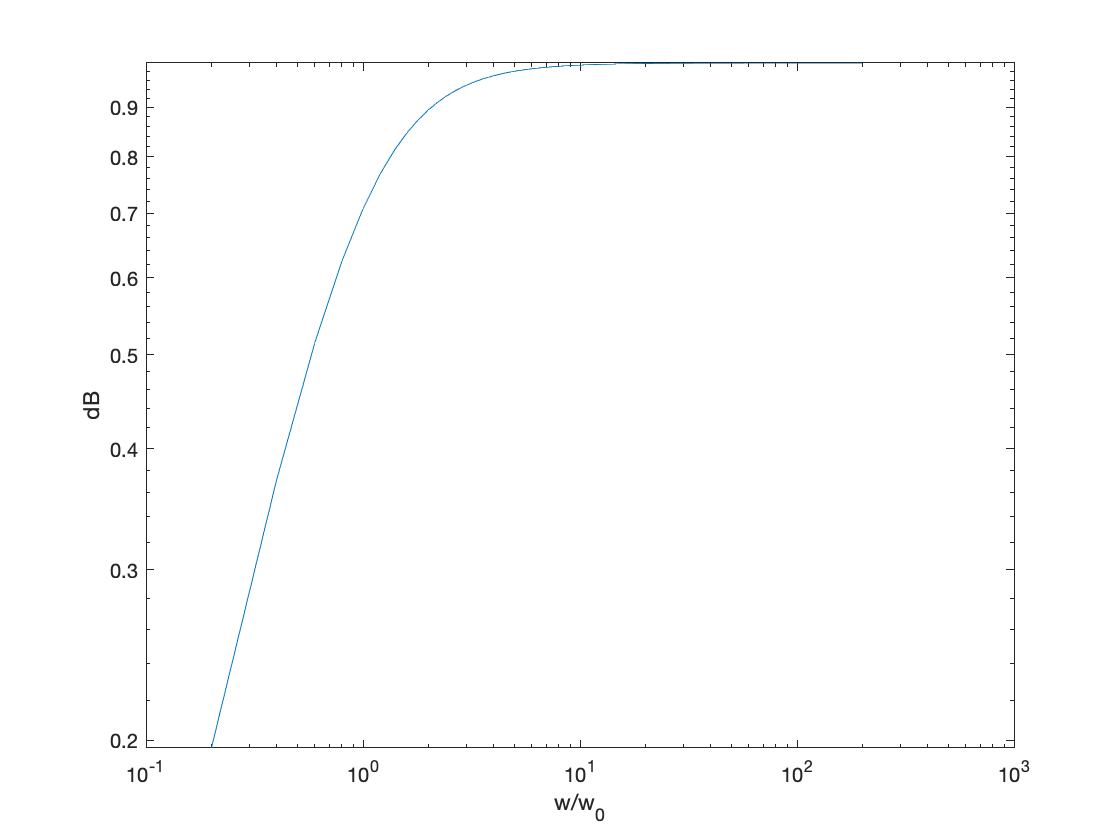


f(x) = @(x) T;
x = linspace(0, 200, 1000);
loglog(x, f(x))
xlabel("w/w_0")
ylabel("dB")

## Notch Filter - Symbolic

syms R L C omega omega_LR omega_LC Z_R Z_L Z_C Z_LC V_out V_in T x
% dont confuse matlab,
assume(omega>0)
assume(omega_LR>0)
assume(omega_LC>0)
assume(T>0)
assume(R>0)
assume(L>0)
assume(C>0)

Z_R = R;
Z_C = -1i/(omega*C);
Z_L = 1i*L*omega;
Z_LC = (Z_L*Z_C)/(Z_L+Z_C);
Z_LC = simplify(Z_LC);
V_out = V_in*(Z_R/(Z_LC + Z_R));

[num, denom] = numden(V_out);
num = simplify(-num/((C*L*omega^2-1)*1i));
num = num*(1/R);
denom = -denom/((C*L*omega^2-1)*1i);
denom = denom*(1/R);
denom = simplify(denom, 'Steps', 50);

z = 1/denom;
z_conj = conj(z);
T = sqrt(z*z_conj);

old = [1/(L*C), R/L];
new = [omega_LC^2, omega_LR];

T = subs(T, old, new);
T = subs(T, omega/omega_LC, x); % x is symbolic

T1 = subs(T, omega/omega_LR, 1);
T1 = simplify(T1);

T2 = subs(T, omega/omega_LR, 0.5);
T2 = simplify(T2);

T3 = subs(T, omega/omega_LR, 1.5);
T3 = simplify(T3);

f1(x) = @(x) T1;

Error using sym/subsindex (line 825)
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

%f2(x) = @(x) T2;
%f3(x) = @(x) T3;

x = linspace(0, 100, 1000);

loglog(x, f1(x))
%hold on
%loglog(x, f2(x))
%loglog(x, f3(x))
xlabel("w/w_0")
ylabel("dB")
%hold off